Problem 3.2

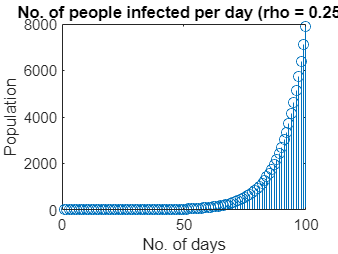

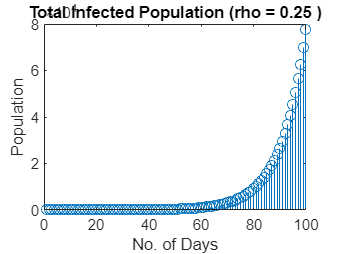

Total_infected_people_4 = 7.7745e+04

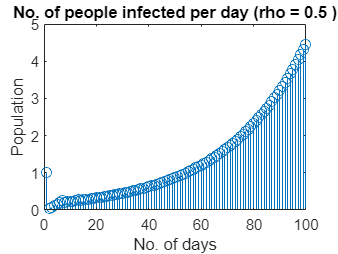

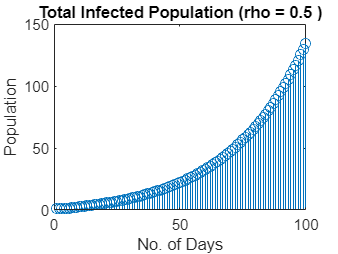

Total_infected_people_4 = 133.8987

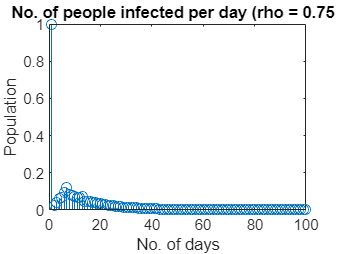

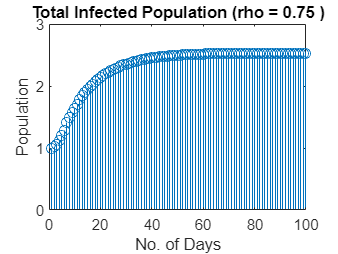

Total_infected_people_4 = 2.5310

ak = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b4 = 1;
rho1 = [0.25 0.5 0.75];
N2 = 1:100;

for i = rho1 ;
    a4 = [1 -(1-i)*ak];
    figure;
    sys6 = tf(b4,a4,1,"Variable" ,"z^-1"); % defines transfer function
    sys7 = filter( b4, a4, var);
    stem(N2,sys7)
    title("No. of people infected per day (rho = "+i+" )")
    ylabel("Population")
    xlabel("No. of days")
    figure;
    I4 = filter(b1,a1,sys7);
    stem(I4)
    title("Total Infected Population (rho = "+i+" )")
    ylabel("Population")
    xlabel("No. of Days")
    figure;
    Total_infected_people_4 = I4(end)
end